clear

% Bilderna sökväg
imagePath = '../HDR/ImagesSmall/';

% Alla tiff-filer i mappen
imageList = dir(fullfile(imagePath, '*.tiff'));
imageAmount = numel(imageList);


%Första bilden
firstImage = imread(fullfile(imagePath, imageList(1).name));

% Hämta storleken på den första bilden
[row, col, channel] = size(firstImage);

%Initialize allImages
allImages = zeros(row, col, channel, imageAmount);

%Sparar alla bilder i allImages
for i = 1:imageAmount
    allImages(:,:,:,i) = imread(fullfile(imagePath, imageList(i).name));
end



% for i=1:imageAmount
%     figure;
%     imshow(allImages(:,:,:,i));
% end

%Slumpa pixelpositioner
pixelSamples = 500;

x = randi([1, row], 1, pixelSamples);
y = randi([1, col], 1, pixelSamples);

%Skapar Z(i,j) för alla tre kanaler
Z_red = zeros(pixelSamples ,imageAmount);
Z_green = zeros(pixelSamples ,imageAmount);
Z_blue = zeros(pixelSamples ,imageAmount);

for j = 1:imageAmount
    for i =1:pixelSamples 
        Z_red(i,j) = allImages(x(i), y(i), 1, j);
        Z_green(i,j) = allImages(x(i), y(i), 2, j);
        Z_blue(i,j) = allImages(x(i), y(i), 3, j);
    end
end


%B(j)
%%TODO Skriv in delta t manuellt

B = zeros(imageAmount,1);
lowestExposure = 1/4000;
B(1) = lowestExposure;

for j = 2:length(B)
    B(j) = B(j-1) * 2;
end

% B(2) = 1/2000; 
% B(3) = 1/1000;
% B(4) = 1/500;
% B(5) = 1/250;
% B(6) = 1/125;
% B(7) = 1/60;
% B(8) = 1/30;
% B(9) = 1/15;
% B(10) = 1/6;
% B(11) = 1/3;
% B(12) = 0.6;
% B(13) = 1.3;

B = log(B)

B =    -8.2940
   -7.6009
   -6.9078
   -6.2146
   -5.5215
   -4.8283
   -4.1352
   -3.4420
   -2.7489
   -2.0557


%lambda, mellan (0 - 1)

lambda = 100;

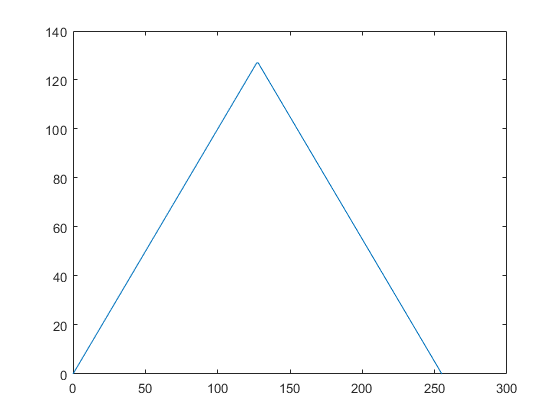

% Skapar den viktade funktionen
w = hat(0:255);
%w = gaussian(0:255);
x = linspace(0,255, 256);

figure;
plot(x,w)

%Beräknar g-kurvan och log(E) med funtionen gsolve
[gCurveRed,lERed] = gsolve(Z_red,B,lambda,w);
[gCurveGreen,lEGreen] = gsolve(Z_green,B,lambda,w);
[gCurveBlue,lEBlue] = gsolve(Z_blue,B,lambda,w);


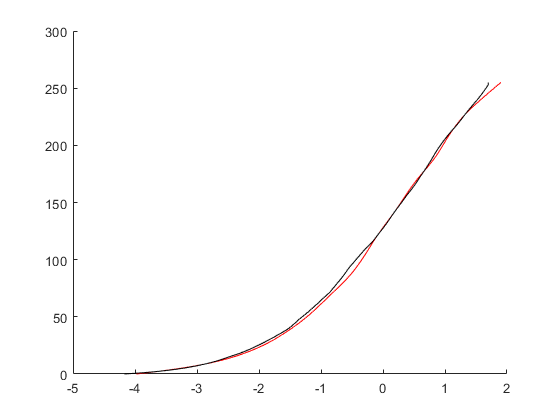


gCurve2 = makegfun;
y = linspace(0, 255, 256)';


figure;
hold on;
plot(gCurveRed, y, 'r-');
plot(gCurve2(:,1), y, 'k'); %Facit

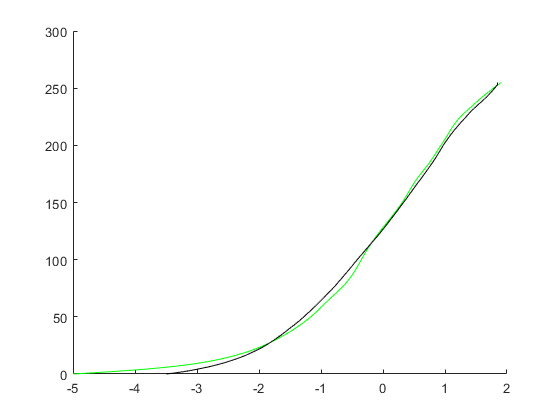


figure;
hold on;
plot(gCurveGreen, y, 'g-');
plot(gCurve2(:,2), y, 'k'); %Facit

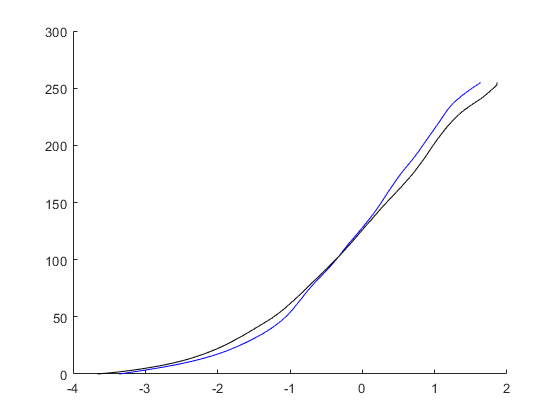


figure;
hold on;
plot(gCurveBlue, y, 'b-');
plot(gCurve2(:,3), y, 'k'); %Facit

allImagesRed = im2uint8(squeeze(allImages(:,:,1,:)));
im = createRadianceMap(allImagesRed, gCurveRed, w, B);
max(max(im))

ans = 0

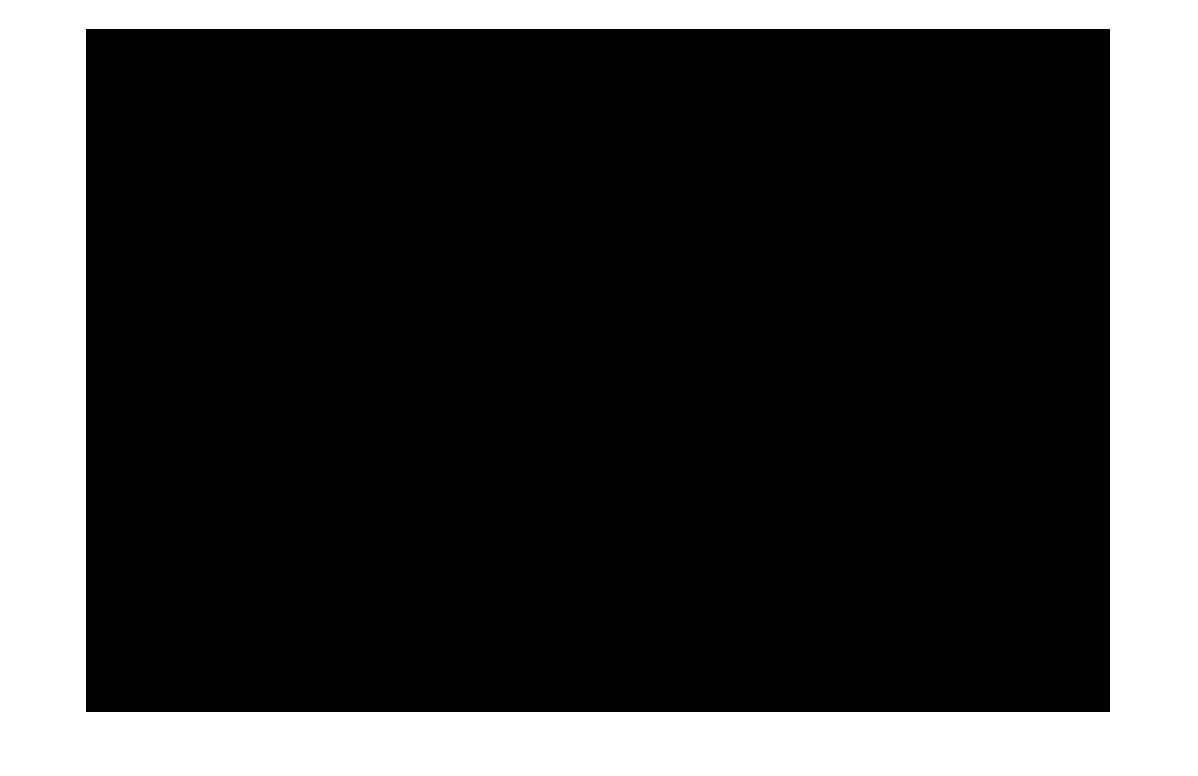


imshow(im);